A=[0 1 1;-4 -1 0;0 0 -1];Bw=[0 0;0.5 0;0 0.4];
C=[1 0 0.05];
n=size(A,1);m=size(Bw,2);
sys=ss(A,Bw,C,0);
Sx_ba=gram(sys,'c');
%augmented matrix
V=1e-2; %Measure noise (integrated).
Qv=sqrtm(V);
Abig=[A zeros(n,1);C 0];
Bbig=[Bw zeros(n,1);zeros(1,m) Qv];
Cbig=[zeros(1,n) 1];
Sbig_ba=blkdiag(Sx_ba,0);

**2 "best" optimal measures, dynamic programming:**

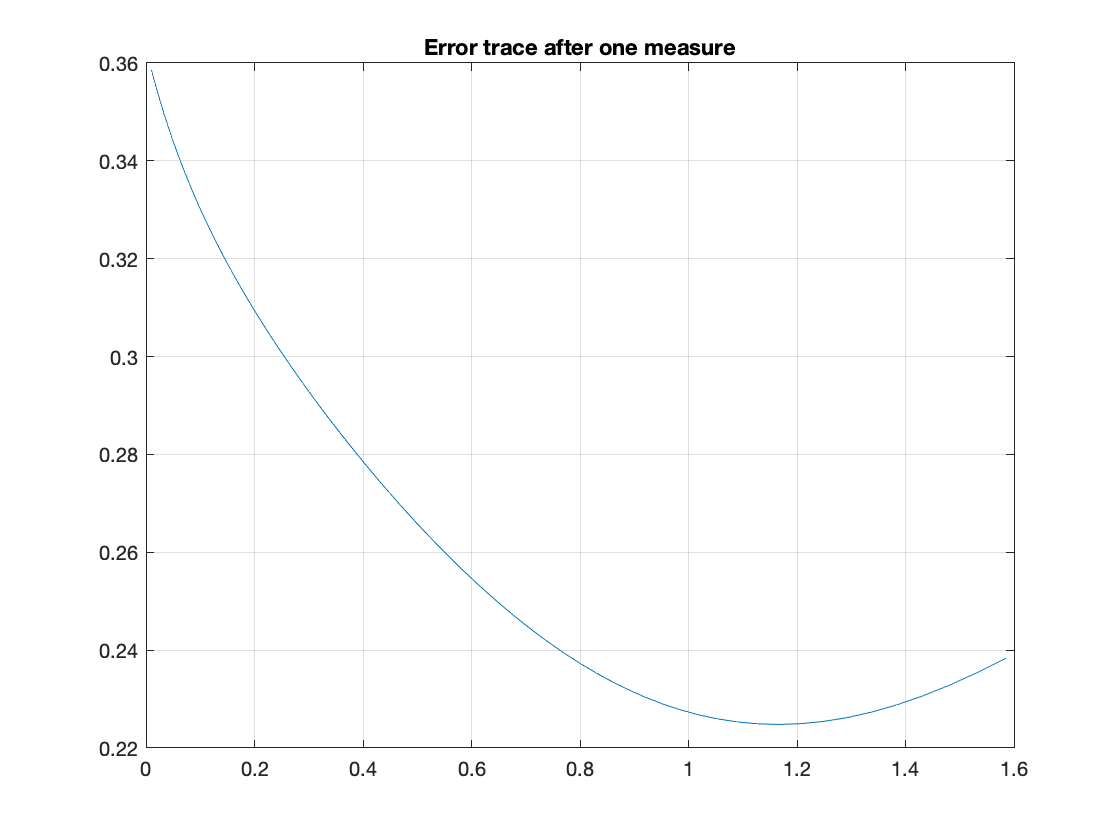

tic
N=2; %Nº of measuring points
N1=150;
Tsrango=logspace(-2,0.2,N1);
J=zeros(1,N1);
for i=1:N1
    [J(i),Sx_post]=Optimal_step(Tsrango(i),Abig,Bbig,Cbig,Sbig_ba);
end
plot(Tsrango,J), grid on
%yline(trace(Sx_ba),'-.',"B. abto")
%yline(trace(Sx_post),'-.',"1 medida")
title("Error trace after one measure")

[Jmin,i1min]=min(J);
Ts=Tsrango(i1min);
fprintf("Best option 1 measure Ts=%g, J=%d",Ts,Jmin)

Best option 1 measure Ts=1.16712, J=2.248171e-01

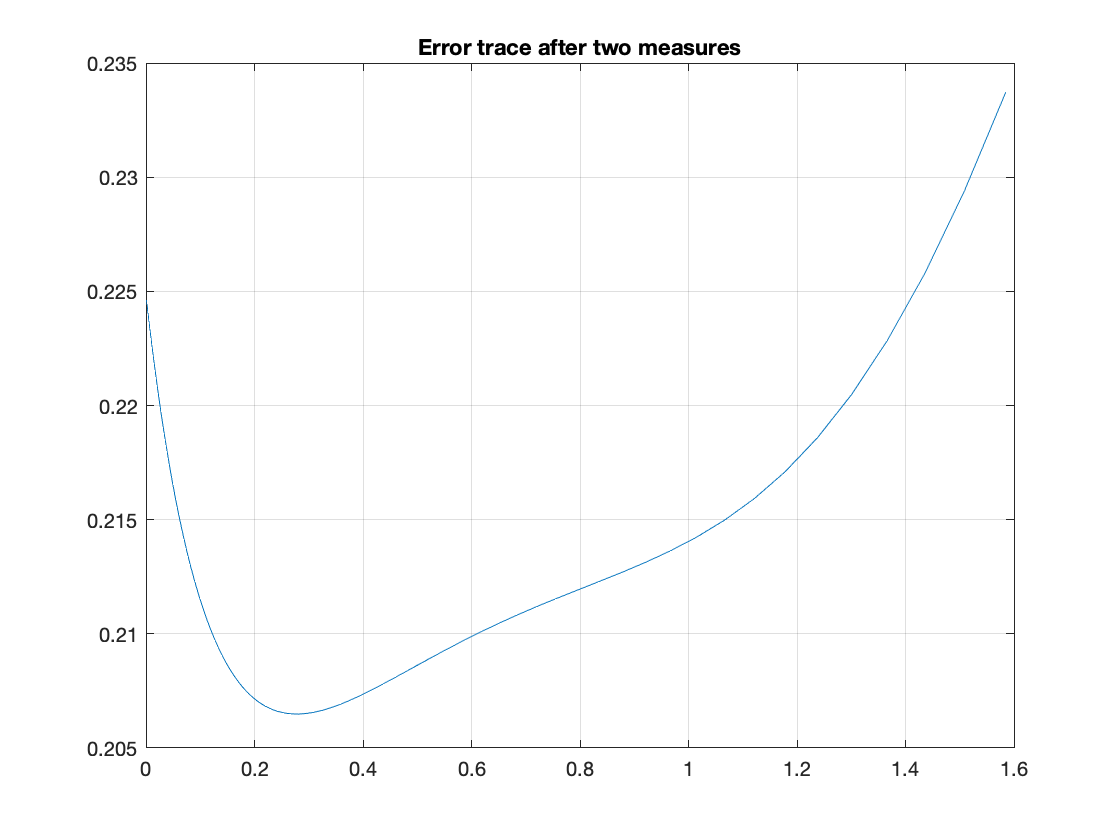

Tsrango11=Tsrango;
J11=J;
%%%%%%%%%%%%%%%%%%%%
N2=150;
Tsrango2=logspace(-3,0.2,N2);
[J1,Sx_post]=Optimal_step(Tsrango(i1min),Abig,Bbig,Cbig,Sbig_ba);
Ts11=Tsrango(i1min);
J2=zeros(1,N2);
for i=1:N2
    [J2(i),Sx_post2]=Optimal_step(Tsrango2(i),Abig,Bbig,Cbig,Sx_post);
end
plot(Tsrango2,J2), grid on
%yline(trace(Sx_ba),'-.',"B. abto")
%yline(trace(Sx_post),'-.',"1 medida")
title("Error trace after two measures")

[J2min,i2min]=min(J2);
%J2min;
Tsrango12=Tsrango2;
J12=J2;
fprintf("Best (for now...!) option 2 measures Ts1=%g, Ts2= %g, J=%d",Tsrango(i1min),Tsrango2(i2min),J2min)

Best (for now...!) option 2 measures Ts1=1.16712, Ts2= 0.280752, J=2.064869e-01

toc

Elapsed time is 0.432971 seconds.


[Jdef,Sdef]=Optimal_step(Tsrango2(i2min),Abig,Bbig,Cbig,Sx_post);

**Brute force**

J3=zeros(N1,N2);
J6=zeros(N1,N2);
for i=1:N1
[JF1,SF1]=Optimal_step(Tsrango(i),Abig,Bbig,Cbig,Sbig_ba);
    for j=1:N2
        [J3(i,j),SF2]=Optimal_step(Tsrango2(j),Abig,Bbig,Cbig,SF1);
        J6(i,j)=trace(SF2-Sdef);
    end
end
J3(i1min,i2min) %Check that is the same model:

ans = 0.2065

fprintf("Above: the 'best' result obtained with dynamic programming")

Above: the 'best' result obtained with dynamic programming

[min_val,idx]=min(J3(:));min_val

min_val = 0.2023

fprintf("The brute force lands in a better error after two measures")

The brute force lands in a better error after two measures

[row,col]=ind2sub(size(J3),idx);
%%%%%
[max,Sx_post]=Optimal_step(Tsrango(row),Abig,Bbig,Cbig,Sbig_ba);
Ts14=Tsrango(row);
J4=zeros(1,N2);
for i=1:N2
    [J4(i),SF2]=Optimal_step(Tsrango2(i),Abig,Bbig,Cbig,Sx_post);
end

%%%%% Plot
surf(Tsrango,Tsrango2,J3'), shading interp
xlabel("Ts1"), ylabel("Ts2")
hold on
plot3(Tsrango11,zeros(length(J11)),J11,'black',"LineWidth",2)
plot3(Ts11*ones(length(J12)),Tsrango12,J12,'black',"LineWidth",2)
plot3(Ts14*ones(length(J12)),Tsrango12,J4,'red',"LineWidth",2)
plot3(Tsrango(row),Tsrango2(col),min_val,'*r','MarkerSize',12)
plot3(Tsrango(i1min),Tsrango2(i2min),J3(i1min,i2min),'*k','MarkerSize',12)
fprintf("The black cross is not optimal for two measures")

The black cross is not optimal for two measures

fprintf("The red cross, best measure times, is not obtained after reaching the best first measure time (the intersection between the two black lines)") 

The red cross, best measure times, is not obtained after reaching the best first measure time (the intersection between the two black lines)

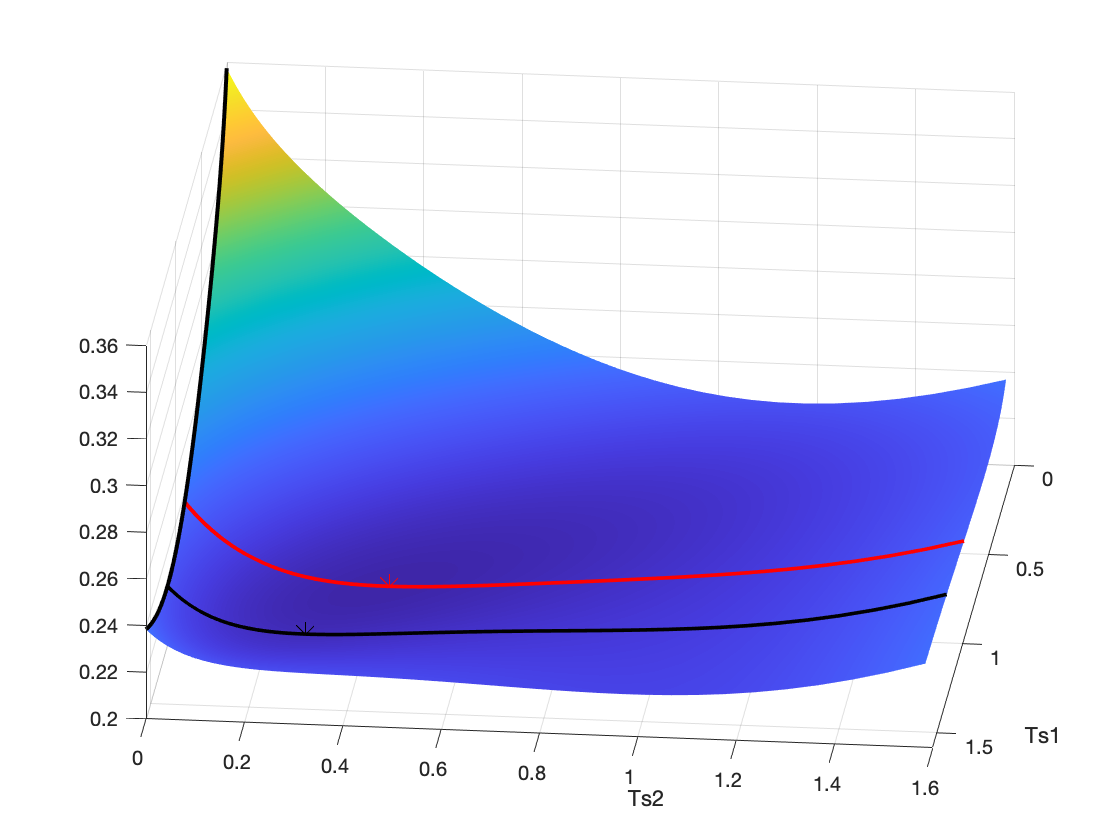

hold off
view([95.894 37.299])

fprintf("Best option 2 measures Ts1=%g, Ts2= %g, J=%d",Tsrango(row),Tsrango2(col),min_val)

Best option 2 measures Ts1=0.830736, Ts2= 0.416998, J=2.023264e-01

%%%%
%%%%% Plot
figure
surf(Tsrango,Tsrango2,J3'), shading interp
xlabel("Ts1"), ylabel("Ts2")
hold on
plot3(Tsrango11,zeros(length(J11)),J11,'black',"LineWidth",2)
plot3(Ts11*ones(length(J12)),Tsrango12,J12,'black',"LineWidth",2)
plot3(Ts14*ones(length(J12)),Tsrango12,J4,'red',"LineWidth",2)
plot3(Tsrango(row),Tsrango2(col),min_val,'*r','MarkerSize',12)
plot3(Tsrango(i1min),Tsrango2(i2min),J3(i1min,i2min),'*k','MarkerSize',12)
fprintf("It may be thought that the black cross has landed in a local minimum, but in this zoom it can be clearly seen that this hypotetical local minimum doesn't exists") 

It may be thought that the black cross has landed in a local minimum, but in this zoom it can be clearly seen that this hypotetical local minimum doesn't exists

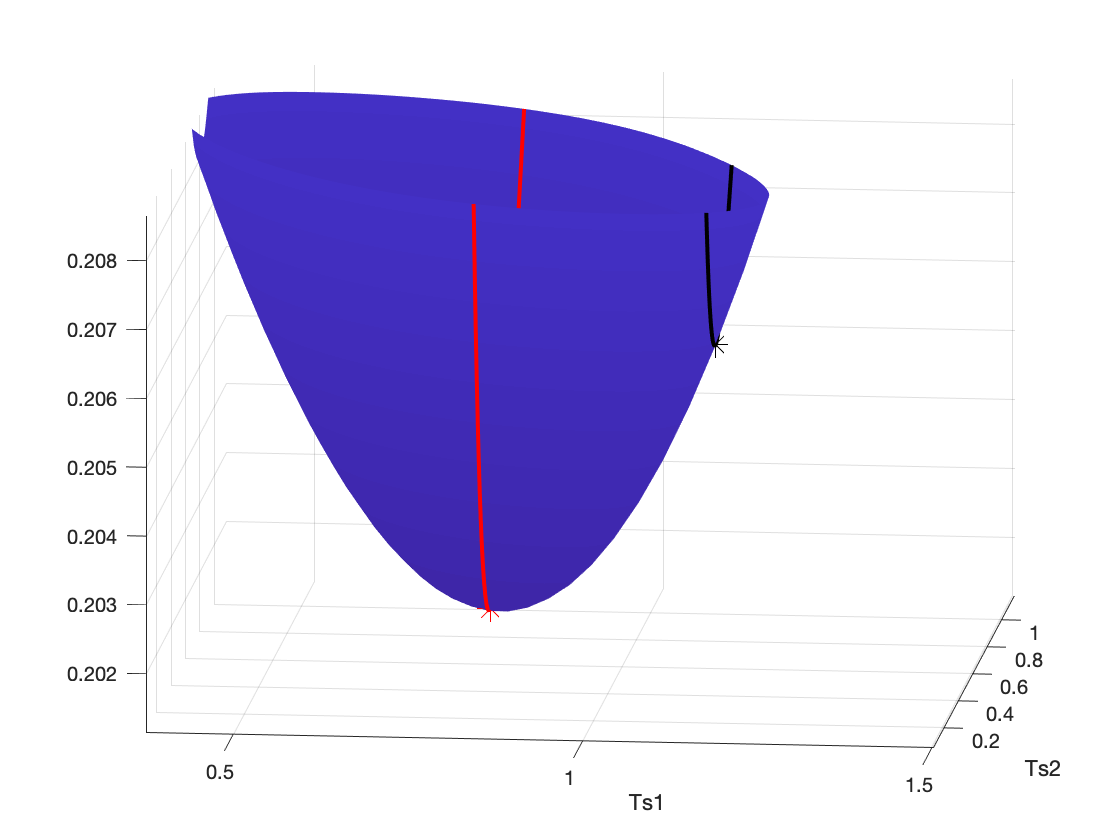

hold off
xlim([0.375 1.502])
ylim([0.051 1.178])
zlim([0.20115 0.20866])
view([5.86396 16.48931])

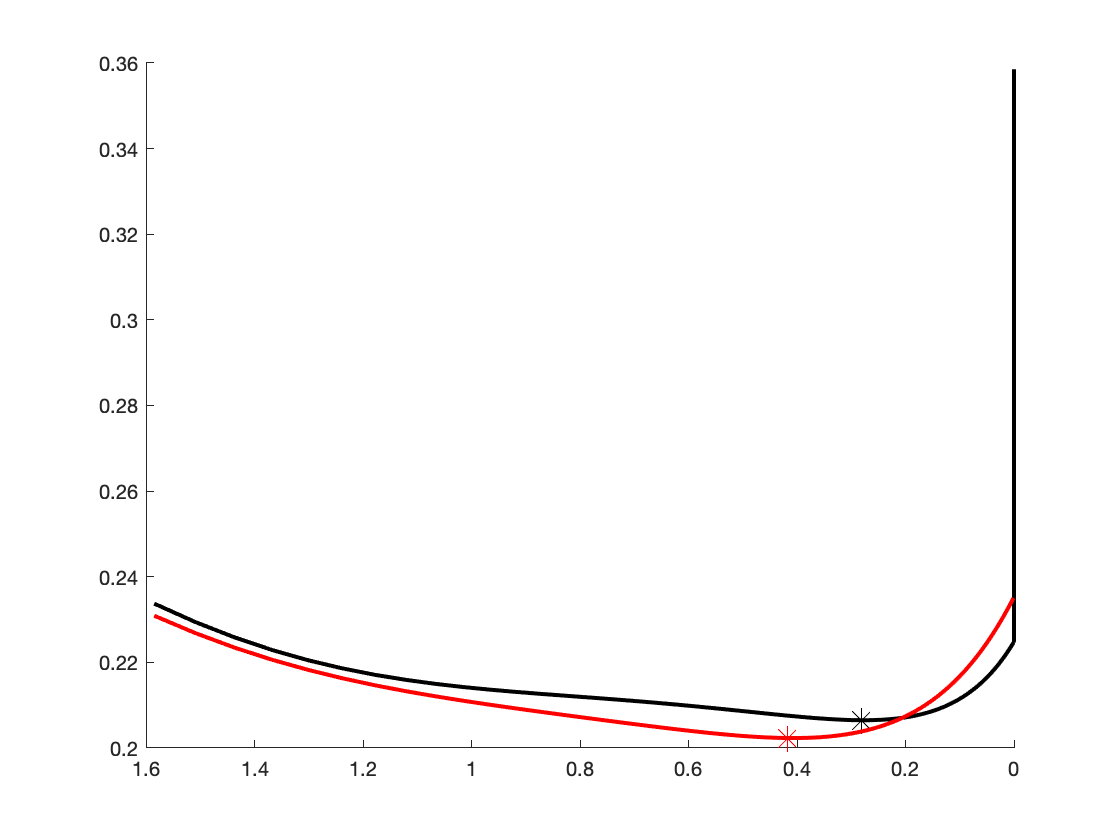

%%%%%
figure
plot3(Tsrango11,zeros(length(J11)),J11,'black',"LineWidth",2)
hold on
plot3(Ts11*ones(length(J12)),Tsrango12,J12,'black',"LineWidth",2)
plot3(Ts14*ones(length(J12)),Tsrango12,J4,'red',"LineWidth",2)
plot3(Tsrango(row),Tsrango2(col),min_val,'*r','MarkerSize',12)
plot3(Tsrango(i1min),Tsrango2(i2min),J3(i1min,i2min),'*k','MarkerSize',12)
hold off
view([-90 0])

fprintf("Dynamic programming won't work. The lines cross, the optimal minimum error after two measures is reached from a non-optimal first measure time (red line)")

Dynamic programming won't work. The lines cross, the optimal minimum error after two measures is reached from a non-optimal first measure time (red line)

function [J,Sx_post] = Optimal_step(mu,Abig,Bbig,Cbig,Sx_act)
    Ad=expm(Abig*mu);
    Wd=c2dvariance(Abig,Bbig*Bbig',mu);
    Sx_next=Ad*Sx_act*Ad'+Wd;
    Sy=Cbig*Sx_next*Cbig'+1e-16;
    Sxy=Cbig*Sx_next;
    Syx=Sxy';
    L=Syx/Sy;
    Sx_post=Sx_next-L*Sxy;
    J=trace(Sx_post);
end
function [Wd,Bd_noise]=c2dvariance(A,Wc,Ts)
  n=size(A,1); %A must be square.
  Phi=expm([-A Wc;zeros(n,n) A']*Ts);
  Wd=Phi((n+1):end,(n+1):end)'*Phi(1:n,(n+1):end);
  [V,Dia]=eig(Wd);
  qx=find(abs(diag(Dia))>1e-12);
  Bd_noise=V(:,qx)*sqrt(Dia(qx,qx)); %raíz cuadrada de Wd (matricial)
end
